# Проверка правильности графиков

## Графические объекты в MATLAB

Начиная с версии R2014a, в MATLAB были представлены графические объекты.

Графический объект - это переменная, содержащая ссылку на элемент графики. Каждая такая переменная имеет свои свойства и методы (терминология ООП).

Существуют графические объекты для фигур, осей, и графиков:

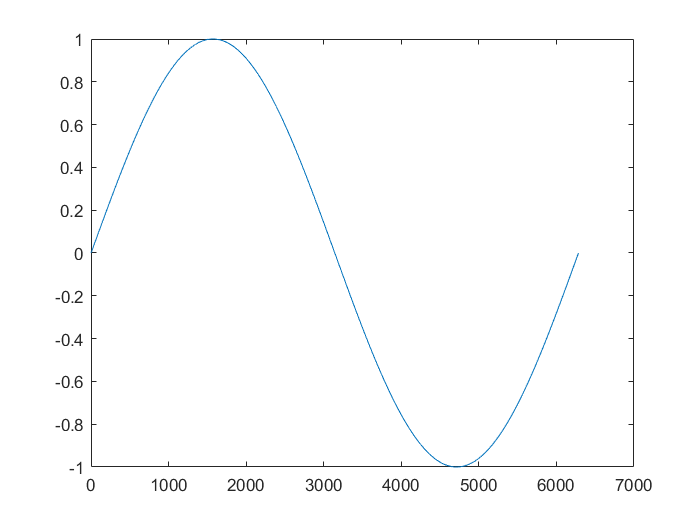

fg = figure;
ax = axes;
pl = plot(sin(0:0.001:2*pi));


whos fg ax pl

  Name      Size            Bytes  Class                                   Attributes

  ax        1x1                 8  matlab.graphics.axis.Axes                         
  fg        1x1                 8  matlab.ui.Figure                                  
  pl        1x1                 8  matlab.graphics.chart.primitive.Line              



У каждого графического объекта есть 2 важных свойства:

- Children - дочерний объект

- Parent - родительский объект

Так, например для осей родителем будет фигура, а дочерним объектом - линия:

class(ax.Parent)

ans = 'matlab.ui.Figure'

class(ax.Children)

ans = 'matlab.graphics.chart.primitive.Line'

Преимущество графических объектов заключается в том, что пользователь может менять их **свойства **не переключаясь между фигурами

**ВАЖНО! Графические объекты не исчезают из рабочей области после закрытия фигуры!**

Больше о графических объектах вы можете узнать из [справки](https://www.mathworks.com/help/releases/R2019a/matlab/graphics-objects.html)

## Использование графических объектов для проверок графиков

В начале live-скрипта мы получили несколько графических объектов. На самом деле, для простейших графиков не имеет смысла создавать фигуру, оси и линию отдельно. Создадим объект линии напрямую вызвав команду **plot():**

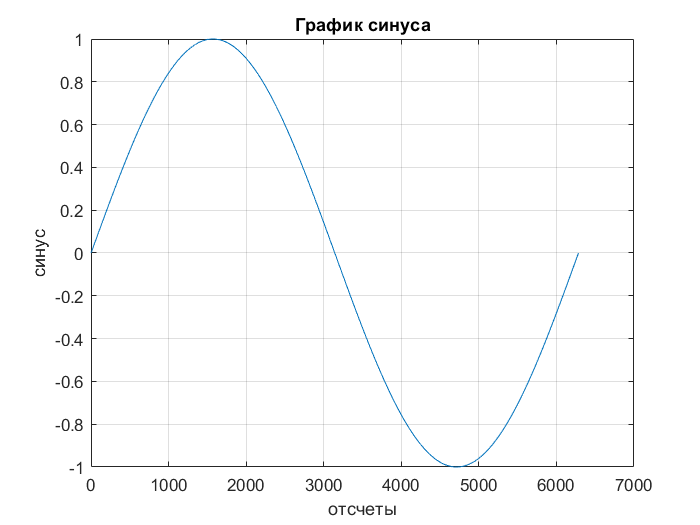

% Удалим старые объекты:
clear ax fg pl
% Построим график заново:
pl = plot(sin(0:0.001:2*pi));
% Настройка графика
grid on
title('График синуса')
xlabel('отсчеты')
ylabel('синус')

Сразу отметим, что само наличие объекта **pl **является субъектом проверки!

Допустим, что требуется проверить наличие сетки и подписей к графику. Мы знаем, что сетка и подписи - это свойства осей. Поэтому нам надо получить доступ к осям, используя свойство Parent объекта **pl:**

plax = pl.Parent;
class(plax)

ans = 'matlab.graphics.axis.Axes'

Теперь мы можем исследовать его свойства:

- Наличие сетки (**'on'**  указывает на наличе сетки)

plax.XGrid

ans = 'on'

plax.YGrid

ans = 'on'

- Наличие подписей к осям и название графика

plax.XLabel.String

ans = 'отсчеты'

plax.YLabel.String

ans = 'синус'

plax.Title.String

ans = 'График синуса'

Таким образом, проверка на включенную сетку будет выглядить так:

XGridState = strcmp(plax.XGrid,'on');
YGridState = strcmp(plax.YGrid,'on');
assert(XGridState & YGridState);

Наличие же подписей к графику проверяется так:

existXlabel = ~isempty(plax.XLabel.String);
existYlabel = ~isempty(plax.YLabel.String);
existTitle  = ~isempty(plax.Title.String);
assert(existTitle & existXlabel & existYlabel);

Кроме того, что мы хотим проверить корректность оформления графика, иногда мы хотим убедиться, что график был построен с использованием правильных данных. Для этого мы должны получить данные из графика и сравнить их со своим решением:

% создадим в рамках демонстрации опорную переменную sinref
sinref = sin(0:0.001:2*pi);
% сравним данные графика и опорную переменную:
assert(all(sinref == pl.YData));

Как видно, мы можем получать данные о точках графика напрямую из графического объекта!